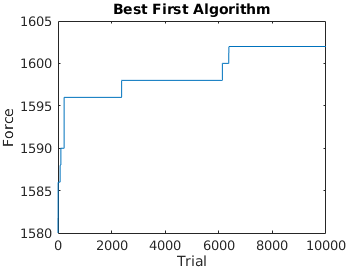

% Creating n Corticalspinal cells
n = 2000;

% Initalize the base CS cells
x_0 = rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor cells
c_fi = create_c_i(0.7, n);  % Flexor CS cells with 70% of 1
c_ei = create_c_i(0.3, n);  % Extensor CS cells with 30% of 1

% Translating MN pool to force
delta = 1;

forces = [];
final_forces = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:n
        s_fi = s_fi + g_i(x_i(i), c_fi(i));
        % s_fi = s_fi + x_i(i) * c_fi(i);
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:n
        s_ei = s_ei +  g_i(x_i(i), c_ei(i));
        % s_ei = s_ei + x_i(i) * c_ei(i);
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end

    trials = [trials, trial];
    % forces = [forces, f_net];
    final_forces = [final_forces, f_final_net];
end

% plot(trials, forces, trials, final_forces)
plot(trials, final_forces)
title("Best First Algorithm")
ylabel('Force')
xlabel('Trial')

saveas(gcf,'BestFirstAlgo.png')

Positive saturation limit for excitatory cells (saturation limit is +1) and Negative saturation limit for inhibitory cells (saturation limit is -1)

function s = g_i(c_i, x_i)
    s = -1;
    if c_i * x_i > 0
        s = 1;
    end
end

function c_i = create_c_i(percentage, n)
    c_i_percentage = percentage;
    num_of_ones_i = round(n * c_i_percentage);
    % Create percentage of 1
    c_i = [ones(1, num_of_ones_i), zeros(1, n - num_of_ones_i)];
    % c_i shuffle it
    c_i = c_i(randperm(length(c_i)));
end